# Support Vector Machine vs. Random Forest Classifier Evaluation

Đánh giá và so sánh mô hình SVM (RBF Kernel) và Random Forest trên bộ đặc trưng dung hợp (Hình thái + Màu sắc HSV + Kết cấu GLCM).

## 1. ĐÁNH GIÁ CÁC MÔ HÌNH HỌC MÁY (EVALUATION)

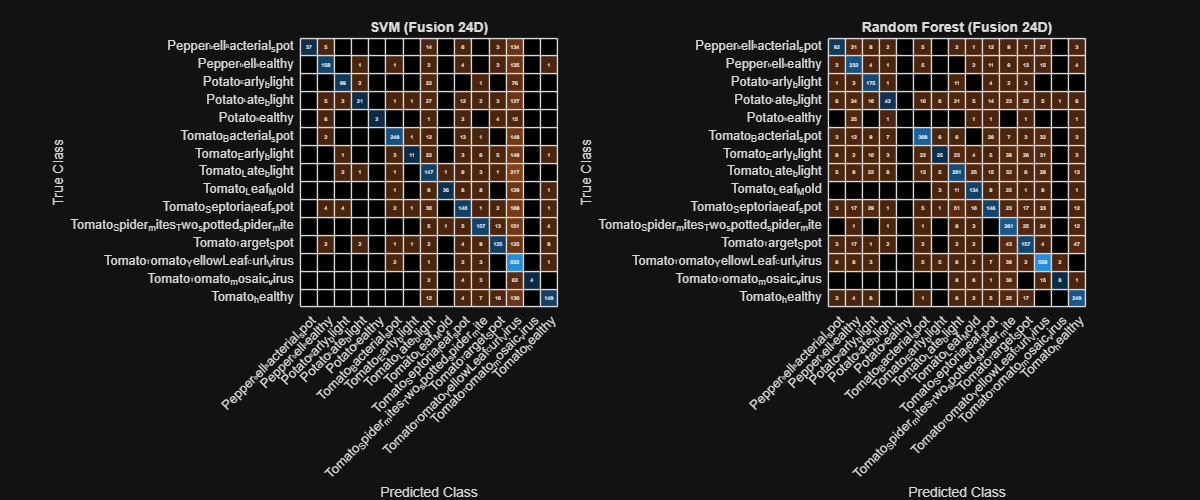


% =======================================================
% 1. ĐÁNH GIÁ CÁC MÔ HÌNH HỌC MÁY (EVALUATION)
% =======================================================

% Thêm thư mục 'reports' vào đường dẫn nhận diện của MATLAB 
% (Giúp MATLAB tự tìm file bất kể bạn đang đứng ở thư mục gốc hay thư mục notebooks)
if exist('../reports', 'dir')
    addpath('../reports');
elseif exist('reports', 'dir')
    addpath('reports');
end

% Đọc kết quả đã lưu (Chỉ cần gọi tên file)
load('fusion_results.mat');
load('bovw_results.mat');

% 1. Vẽ Confusion Matrix cho hệ FUSION
figure('Position', [100, 100, 1200, 500]);
subplot(1,2,1);
confusionchart(Y_test, predictions_fusion{1}, 'Title', 'SVM (Fusion 24D)');
subplot(1,2,2);
confusionchart(Y_test, predictions_fusion{2}, 'Title', 'Random Forest (Fusion 24D)');

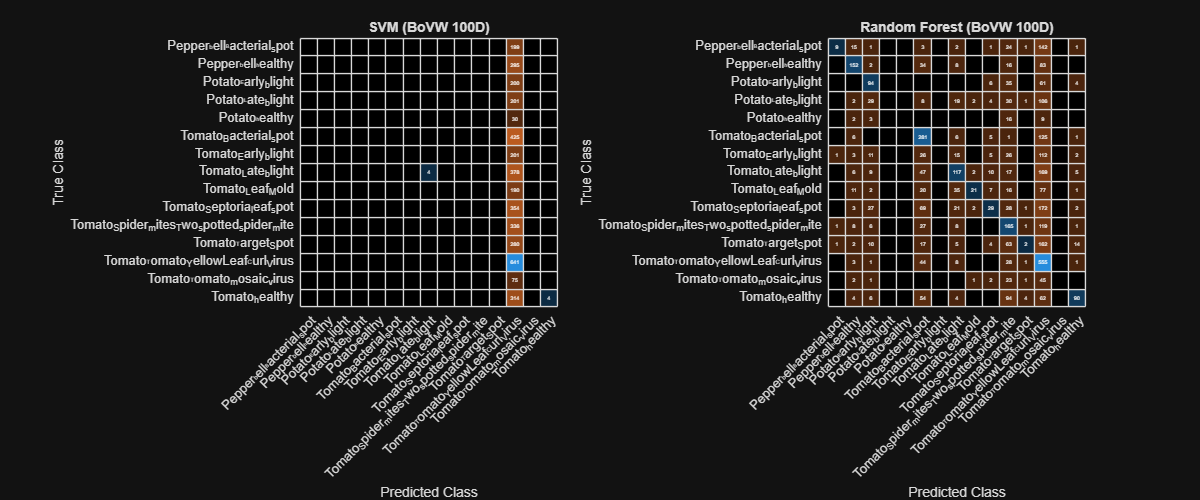


% 2. Vẽ Confusion Matrix cho hệ BoVW
figure('Position', [100, 100, 1200, 500]);
subplot(1,2,1);
confusionchart(Y_test, predictions_bovw{1}, 'Title', 'SVM (BoVW 100D)');
subplot(1,2,2);
confusionchart(Y_test, predictions_bovw{2}, 'Title', 'Random Forest (BoVW 100D)');